# Title

## Title 1

### Title 2

#### Title 3

Text

# L


$$e^{-i\pi}$$


- Why are prticles identical to each other?

- Is there a way to know, in advanced, how many constats of nature are there?

- Is there a way to know, in advanced, how many perticles are in a unit volume?

- $F\propto \frac{1}{r^2 }$ ?

- What is the radial profile of space density?

- Cells: Voronoi? Does it matter?

- Quarks orbitals, continous, with outcomes of charge, spin, mass 'as if' there are quarks?

- A tensor that describes the interactions of space deformations?

- Is there somewhere equal partition of energy?

- Thermodynamics, entropy

- Justification for r0 as half the energy in two sides?

- Anti mass or anti gravity?

- Terms:

-     Ricci flow

-     Deformation

-     Mass

-     Curvature

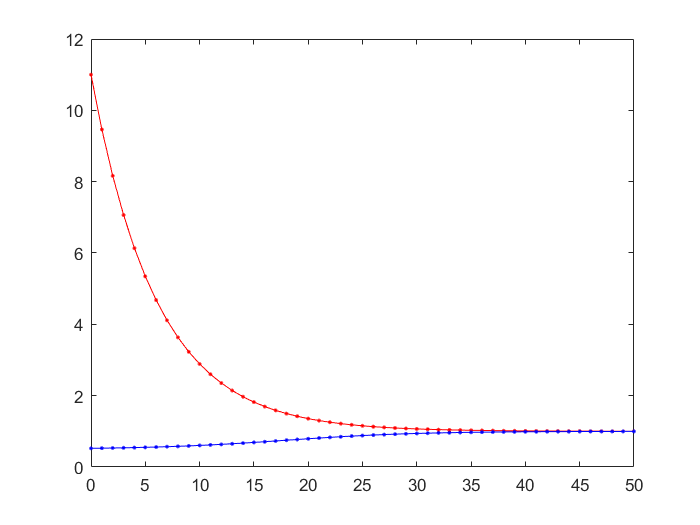

% Set initial radial distancesÉ
dr_0 = 1;
grid_size = 100;
x_0 = -ceil(grid_size/2):dr_0:ceil(grid_size/2);

rho_0 = 1;
r_0 = 0:dr_0:floor(grid_size/2);
sigma_r = 6;
rho_max = 10;

% rho1_p = rho_0*(1 + rho_max*exp(-0.5*(r0./sigma_r).^2));
rho1_p = rho_0*(1 + rho_max*exp(-abs(r_0./sigma_r)));
rho1_n = 1./(2./rho_0 - 1./rho1_p);

% Get new r distributions:
delta_1p = 1./rho1_p;
delta_1n = 1./rho1_n;


rp0 = cumsum(delta_1p) - sum(delta_1p(1:floor(grid_size/2)));
rn0 = cumsum(delta_1n) - sum(delta_1n(1:floor(grid_size/2)));
rp = rp0 - min(rp0);
rn = rn0 - min(rn0);

figure(1)
plot(r_0, rho1_p,'r.-')
hold on
plot(r_0, rho1_n,'b.-')
hold off

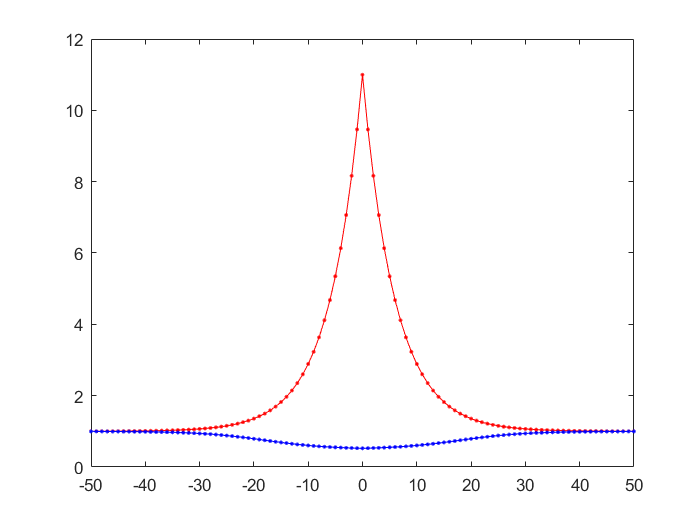

xlabel('r_0')
ylabel('\rho(r_0)')

rho_x_p = rho_0*(1 + rho_max*exp(-abs(x_0./sigma_r)));
rho_x_n = 1./(2./rho_0 - 1./rho_x_p);

% Get new r distributions:
delta_x_p = 1./rho_x_p;
delta_x_n = 1./rho_x_n;

figure(2)
plot(x_0, rho_x_p,'r.-')
hold on
plot(x_0, rho_x_n,'b.-')
hold off

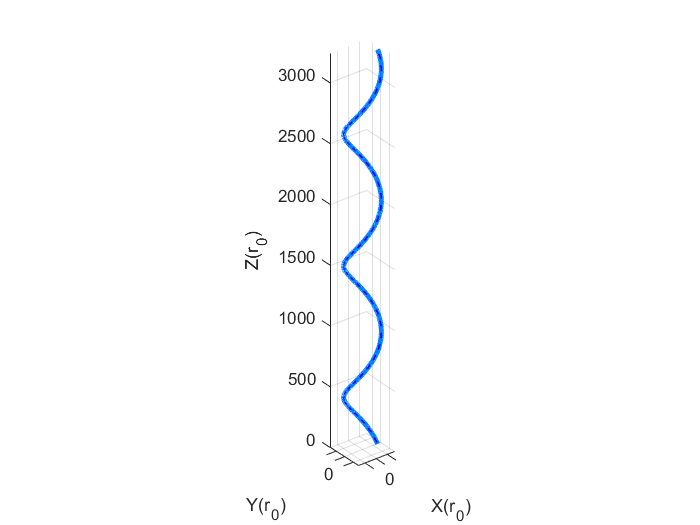


% Spirals2
clear
clc

R0 = 137.0366;

loops = 3;
c = 1;
v = 0.2*c;

c_alpha = 0.5;
N_samples = 5;
cmap = jet(N_samples);

[R_path, r_path] = getSpiralPath(v,loops);
Z = 3000;

figure(14)
clf
plot3(r_path(:,1), r_path(:,2), r_path(:,3), 'b-','LineWidth',1)
hold on
plot3(R_path(:,1), R_path(:,2), R_path(:,3), '-','LineWidth',3,...
    'Color',[cmap(1,:), c_alpha])
hold off

xlabel('X(r_0)')
ylabel('Y(r_0)')
zlabel('Z(r_0)')

axis equal
axis(1.2*[-R0 R0 -R0 R0 -1 inf])
grid on

Adam, Eve, Dirac sea:

#### The photon quantum enigma


$$y=y_0sin(\omega t)$$



$$v=\omega y_0 cos(\omega t)$$



$$a=-\omega ^2 y_0 sin(\omega t)$$



$$U_k={\frac{1}{2}} mv^2={\frac{1}{2}}m\omega ^2 y_0^ ^2cos ^2(\omega t)$$



$$U_p={\frac{1}{2}}ky ^2={\frac{1}{2}}ky_0 ^2 sin ^2(\omega t)$$



$$U=U_k(max)=U_p(max)=m\omega ^2y_0 ^2=ky_0 ^2$$



$$\omega=\sqrt{(\frac{k}{m}})$$



$$U=const \to m={\frac{U}{c ^2}}$$



$$\to U=m\omega ^2 y_0 ^2={\frac{U}{c^2}}\omega ^2 y_0 ^2\to 1={\frac{\omega ^2 y_0 ^2}{c_^2}} $$


$\to c=y_0\omega$, but $c=\omega{\frac{\lambda}{2\pi}}$


$$\to y_0={\frac{\lambda}{2\pi}}$$


We denote $y_0$ as $R_e$ and relate to it as half the “cylinder height”.


$$\alpha={\frac{r_e}{R_e}}$$


This is the same ratio, as it is for the radii of the electron [3] (their sizes are different). From  the geometry of both the electron and the photon it seems that this ratio determines the  probability for the photon to interact with the electron.

Hence  𝑗 = − √α  =−0.08542455 is  the probability amplitude of the QED Junction, Coupling, which is “… one of the greatest  damn mysteries of physics: a magic number”; Feynman [7] in his own words.

Note that the contraction or dilation move at the same velocity c, as the propagation  does, and hence the maximum possible half height of the disturbance is  $H=c{\frac{1}{4}}t={\frac{1}{4}}\lambda$,  whereas  as (5) shows: $R_e={\frac{1}{2}}\lambda$.

#### 5. Photon Energy and the Planck Constant ℏ


$$U=k{\frac{\lambda ^2}{2\pi ^2}}$$


If the “Space Spring Constant K” is a function of ω only we guess that it can be:


$$k=m\omega ^2={\frac{U}{c ^2}}\omega ^2={\frac{\hbar\omega ^3}{c ^2}}$$


where ℏ, not yet identified, is a constant of proportionality.   

Necessarily $U=\hbar\omega$ where  ℏ  becomes the known quantum constant. Thus a classical functionality of $k(\omega)\propto\omega ^3$ leads to the basic quantum mechanical result.

#### 6. The Photon’s Volume

Taking the “cylinder height” as 2Re , gives for the maximum of the oscillatory volume: 


$$V_{photon}=\pi r^2 2R_e={\frac{\alpha ^2}{8\pi^2}}\lambda^2=6.75\cdotp10^{-7}\lambda^3$$


The shorter is λ, the more compact is the photon.

For $\lambda=500nm$ we get: $V_{photon}\sim8\cdotp10^{-20}cm^3$

#### 7. The Photon Spin  

The photon spin L, for a circular polarized photon, is its linear momentum $P={\frac{U}{c}}$ times its  radius of rotation $R_e={\frac{\lambda}{2\pi}}$, $L=PR_e={\frac{U}{c}}{\frac{\lambda}{2\pi}}={\frac{U}{\omega}}$ , but $U=\hbar\omega$, Hence the known result:  L= ℏ.

From: "A Model of The Photons Ground-State Photons and Dirac Sea":


$$y=y_0sin(\omega t)$$



$$v=\omega y_0 cos(\omega t)$$



$$a=-\omega ^2 y_0 sin(\omega t)$$



$$U_k={\frac{1}{2}} mv^2={\frac{1}{2}}m\omega ^2 y_0^ ^2cos ^2(\omega t)$$



$$U_p={\frac{1}{2}}ky ^2={\frac{1}{2}}ky_0 ^2 sin ^2(\omega t)$$



$$U=U_k(max)=U_p(max)={\frac{1}{2}}m\omega ^2y_0 ^2={\frac{1}{2}}ky_0 ^2$$



$$\omega=\sqrt{(\frac{k}{m})}$$



$$U=const \to m={\frac{U}{c ^2}}$$



$$\to U={\frac{1}{2}}m\omega ^2 y_0 ^2={\frac{1}{2}}{\frac{U}{c^2}}\omega ^2 y_0 ^2\to 1={\frac{\omega ^2 y_0 ^2}{2c_^2}} $$


$\to 2c^2=y_0^2\omega ^2$, or $\sqrt{2}c=y_0\omega$

but $c=\omega{\frac{\lambda}{2\pi}}$


$$\to y_0={\frac{\lambda}{\sqrt{2}\pi}}=0.2251\lambda$$


#### 6. Constant k of the “Springy” Space and the Quantization of Energy


$$U={\frac{1}{2}}ky_0 ^2=k{\frac{\lambda^2}{4\pi^2}}$$


Inserting $U={\frac{1}{2}}\hbar\omega={\frac{1}{2}}{\frac{\hbar2\pi c}{\lambda}}={\frac{\hbar\pi c}{\lambda}}$


$$\to k={\frac{4\pi^2 U}{\lambda^2}}={\frac{4\pi^2 \hbar\pi c}{\lambda^3}}={\frac{4\pi^3 \hbar c}{\lambda^3}}$$


"Quantum behavior  of energy is rooted in a classical attribute of space"

#### 7. The Circular Polarized Photon


$$L=mvR$$



$$m={\frac{U}{c^2}}, v=c, R={\frac{Y}{2
}}$$



$$L=\hbar, U={\frac{1}{2}}\hbar\omega$$



$$\to L=\hbar={\frac{U}{c^2
}}c{\frac{Y}{2
}}={\frac{Y}{2}={\frac{\hbar\omega}{c
}}{\frac{Y}{4}}
$$



$$\to 1={\frac{\omega Y}{4c}} \to Y={\frac{4c}{\omega}}=Y={\frac{4c\lambda}{2\pi c}}={\frac{2\lambda}{\pi}}$$


dY = 1;
Y = -10:dY:10; % Cell boundaries in Y direction.
t = 0:0.1:5;
f = 3; % Hz
omega = 2*pi*f;
y0 = 0.2251*dY;
y = y0*sin(omega*t);
[tt,YY] = meshgrid(t,Y);



% Constants
c = 3*10^10; % cm/sec % LT^-1
hbar = 1.0546*10^-27; % erg*sec % L^5T^-1
alpha = 1/137.04;
G = 6.67408*10^-8; % dyne*cm^2/gr^2 % T^-2
% gamma_v = 1/sqrt(1 - v^2/c^2);

Photon:

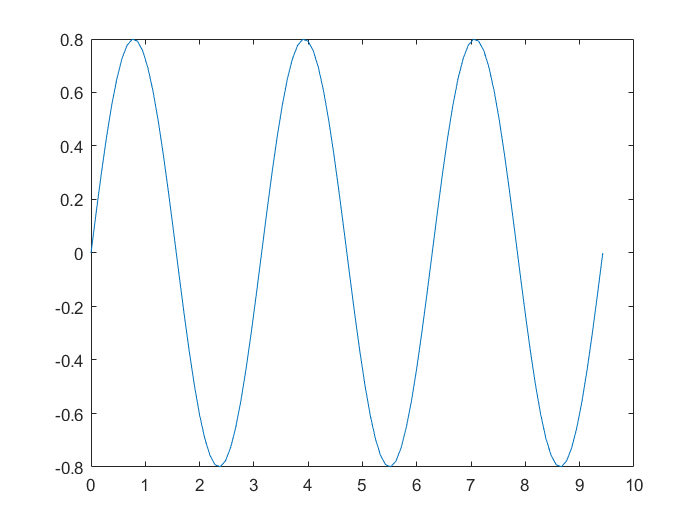

% code2
omega = 2;
t = linspace(0,3*pi,100);
y0 = 0.8;
delta_y = y0*sin(omega*t);
figure(1)
plot(t, delta_y,"-")

Old photon:

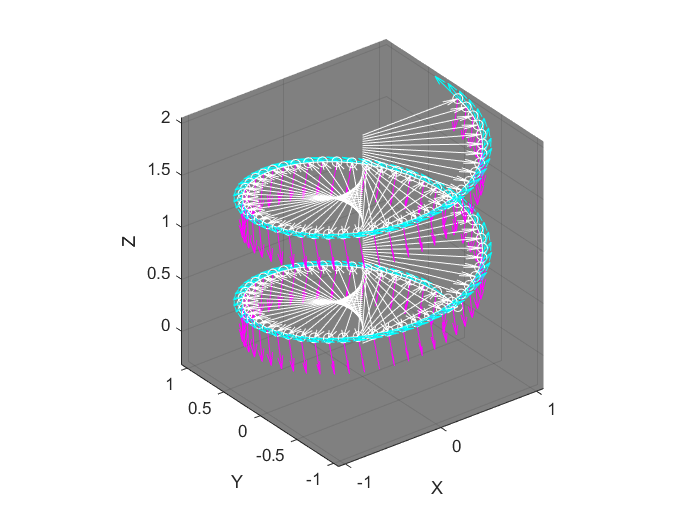

% Photons
clc
clear

%% Plot paths:
delta_t = 0.02;
t = 0:delta_t:2;
R = 1;
theta = 0;
phi = 2*pi;
c = 1;

x = R*cos(phi*t);
y = R*sin(phi*t);
z = t;

% vx0 = R*-sin(phi*delta_t);
% vy0 = R*co(phi*delta_t);
% vz0 = v;

xq = zeros(size(t));
yq = zeros(size(t));
zq = t;

xqv = x;
yqv = y;
zqv = zeros(size(t));

vx = [0, diff(x)/delta_t];
vy = [0, diff(y)/delta_t];
vz = [0, diff(z)/delta_t];

B = cross([vx' vy' vz'],[xqv' yqv' zqv']);
Bx = B(:,1)';
By = B(:,2)';
Bz = B(:,3)';
%
%% Plot figure:
% figure(13)
% clf
plot3(x,y,z,'wo-')
hold on
quiver3(xq,yq,zq,xqv,yqv,zqv,0,'w')
quiver3(x,y,z,vx,vy,vz,1,'c')
quiver3(x,y,z,Bx,By,Bz,1,'m')
hold off
grid on
set(gca,'Color',0.5*[1 1 1])
% axis([-R R -R R 0 max(t)*c])
axis equal
xlabel('X')
ylabel('Y')
zlabel('Z')